# Full Sim Experiment - Nominal

motorRes = [.4 .4 .4 .4];
load params/batteryParams.mat;
load params/Q_coef;
global batteryParams;

% original battery capacitance
Q_orig = 3.8712;

% iterations
k      = 500;

% voltage profiles
v{k,1} = [];

% soc profiles
z{k,1} = [];

% current profiles
c{k,1} = [];

% power profiles
p{k,1} = [];

% ss power vals
pows   = zeros(1,k);

% final landing position  <-- system performance parameter
pos    = zeros(2,k);

% total power consumption <-- system performance parameter
powt   = zeros(1,k);

% motor resistance vals
mval   = zeros(1,k);

% final soc               <-- system performance parameter
soce   = zeros(1,k);

% battery capacitance vals
Qa     = zeros(1,k);

% estimated capacitance
Qe     = Qa;

% predicted capacitance
Qp     = Qa;

% ss rpm
rpms   = zeros(1,k);

% estimated rpm
RPMe   = rpms;

% predicted rpm
RPMp   = rpms;

% prediction horizon
horizon = 10;

% to save eol vals
eolBatt = 0;
eolMot  = 0;
eolSys  = 0;

tic
for i = 1:k+1
    sim('MavicProComplete_oct22');
    v{i}  = voltage_hat.Data;
    z{i}  = soc_hat.Data;
    c{i}  = i_batt.Data;
    p{i}  = power.Data;
    time  = time + tout(end);
    Qa(i) = batteryParams.Q;
    Qe(i) = normrnd(Qa(i), .03);
    
    rpms(i) = rpm.Data(uint16(length(tout)/2));
    RPMe(i) = normrnd(rpms(i), 30);
    pows(i) = power.Data(uint16(length(tout)/2));
    powt(i) = sum(power.Data);
    mval(i) = motorRes(1);
    soce(i) = soc_hat.Data(end);
    
    pos(:,1) = [round(pos(end,1),1), round(pos(end,2),1)];
    
    motorRes(1) = motorRes(1) + .001;
    batteryParams.Q  = polyval(Q_coef, i);
    
       
    save('batteryParams.mat', 'batteryParams');
   
    if i >= horizon
        x = ((i-(horizon-1)):1:i)';
        
        % --------------------------------- Battery -----------------------
        
        q_poly = polyfit(x, smoothdata(Qe((i-(horizon-1)):i), 'rlowess', 5), 1);
 
        q_pred = polyval(q_poly, i+5);
        Qp(i) = q_pred;
        
        q_pred = polyval(q_poly, i+horizon);
        
        if ~maintFlagBatt && q_pred <= maintThreshBatt
            maintFlagBatt = true;
            maintWarnBatt = i;
            disp(["Battery Maintenance threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~maintNoticeBatt && Qe(i) >= .995*maintThreshBatt && Qe(i) <= 1.01*maintThreshBatt
            maintNoticeBatt = true;
            disp(["Battery Maintenance Required. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if ~failFlagBatt && q_pred <= failThreshBatt
            failFlagBatt = true;
            failWarnBatt = i;
            disp(["Battery Failure threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~failNoticeBatt && Qe(i) >= .995*failThreshBatt && Qe(i) <= 1.01*failThreshBatt
            failNoticeBatt = true;
            disp(["Estimated battery failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if Qa(i) <= failThreshBatt
            disp(["Actual battery failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
            break
        end

        % --------------------------------- Motor -----------------------
        
        p_rpm = polyfit(x, smoothdata(RPMe((i-(horizon-1)):i), 'rlowess', 15), 1);
        
        rpm_pred = polyval(p_rpm, i+horizon);
        
        RPMp(i) = polyval(p_rpm, i+5);
        
        if ~maintFlagMot && rpm_pred <= maintThreshMot
            maintFlagMot = true;
            maintWarnMot = i;
            disp(["Motor Maintenance threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~maintNoticeMot && RPMp(i) >= .995*maintThreshMot && RPMp(i) <= 1.01*maintThreshMot
            maintNoticeMot = true;
            disp(["Motor Maintenance Required. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if ~failFlagMot && rpm_pred <= failThreshMot
            failFlagMot = true;
            failWarnMot = i;
            disp(["Motor Failure threshold will be reached at cycle: "  num2str(i+horizon)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~failNoticeMot && RPMp(i) >= .995*failThreshMot && RPMp(i) <= 1.01*failThreshMot
            failNoticeMot = true;
            disp(["Estimated Motor failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if rpms(i) <= failThreshMot
            disp(["Actual Motor failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
            eol = i;
            break
        end

        % --------------------------------- System -----------------------
        
    end
end
toc


motorResults.setRPM = setRPM;
motorResults.failThresh = failThreshMot;
motorResults.failWarn = failWarnMot;
motorResults.rpms = rpms;
motorResults.mvals = mval;
motorResults.RPMe = RPMe;
motorResults.RPMpreds = RPMp;
motorResults.eol = eol;
motorResults.maintWarn = maintWarnMot;
motorResults.maintThresh = maintThreshMot;
motorResults.pgon = pgon;

save('motorResults.mat', 'motorResults');

pgon = polyshape([failWarnBatt failWarnBatt eol eol], [Qa(failWarnBatt)+.03 Qa(failWarnBatt)-.03 Qa(eol)-.03 Qa(eol)+.03]);
batteryResults.Qe    = Qe(1:eol);
batteryResults.preds = preds(1:eol);
batteryResults.Qa    = Qa(1:eol);
batteryResults.pgon  = pgon;
batteryResults.eol   = eol;
batteryResults.v     = v;
batteryResults.z     = z;

batteryResults.maintWarn   = maintWarnBatt;
batteryResults.failWarn    = failWarnBatt;
batteryResults.maintThresh = maintThreshBatt;
batteryResults.failThresh  = failThreshBatt;

batteryParams.Q  = Q_orig;
save('batteryResults.mat', "batteryResults");
save('batteryParams.mat', 'batteryParams');


Elapsed time is 108.915130 seconds.


disp("mission took: " + num2str(tout(end)) + "seconds");

mission took: 501.4408seconds


disp("rpm residual: " + num2str(mean(rpm_res/100)));

rpm residual: 0.24276


disp("cur residual: " + num2str(mean(i_res)));

cur residual: -0.02031


disp("final position: " + num2str(round(pos(end,1),1)) + "," + num2str(round(pos(end,2),1)));

final position: 0.1,2415.5


disp("soc: " + num2str(soc.Data(end)));

soc: 0.62163


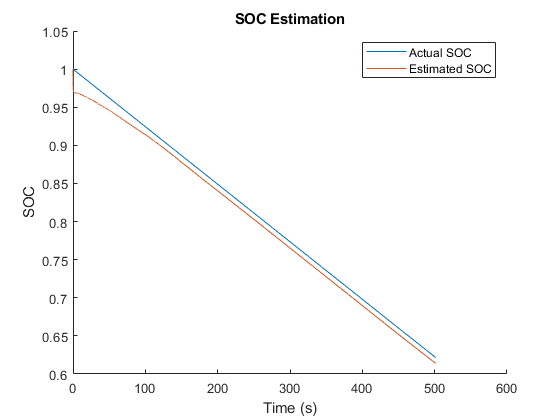

f1 = figure(1); clf;
hold on;
plot(soc.Time, soc.Data);
plot(soc_hat.Time, soc_hat.Data);
title("SOC Estimation");
legend(["Actual SOC", "Estimated SOC"]);
ylabel("SOC");
xlabel("Time (s)");
hold off;

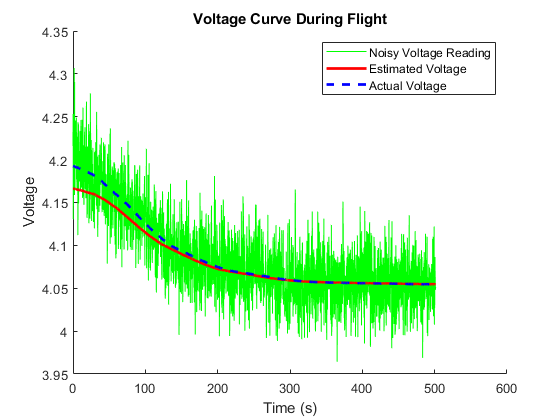

f2 = figure(2); clf;
hold on;
plot(noisy_v.Time, noisy_v.Data, 'g');
plot(v_batt_hat.Time, smoothdata(v_batt_hat.Data, 'movmean', 500), 'r', 'linewidth', 2);
plot(v_batt.Time, smoothdata(v_batt.Data, 'movmean', 500), 'b--', 'linewidth', 2);
hold off;
title("Voltage Curve During Flight");
xlabel("Time (s)");
ylabel("Voltage");
legend(["Noisy Voltage Reading", "Estimated Voltage", "Actual Voltage"]);

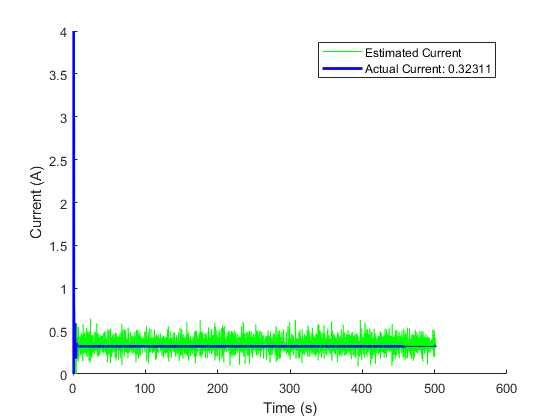

i_hatData = i_hat.Data(1,:);
f3 = figure(3); clf;
hold on;
plot(i_hat.Time, i_hatData, 'g');
plot(i_mot.Time, i_mot.Data, 'b', 'linewidth', 2);
hold off;
% title("Single Motor Current Draw");
xlabel("Time (s)");
ylabel("Current (A)");
legend(["Estimated Current", "Actual Current: " + num2str(i_mot.Data(1000))]);
ylim([0 4]);

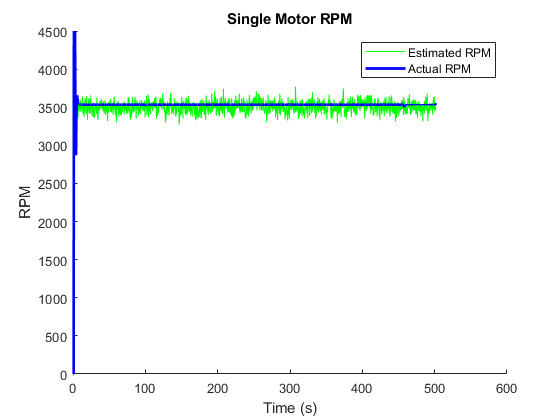

f4 = figure(4); clf;
hold on;
plot(rpm_hat.Time, rpm_hat.Data, 'g');
plot(rpm.Time, rpm.Data, 'b', 'linewidth', 2);
hold off;
xlabel("Time (s)");
ylabel("RPM");
ylim([0 4500]);
title("Single Motor RPM");
legend(["Estimated RPM", "Actual RPM"]);

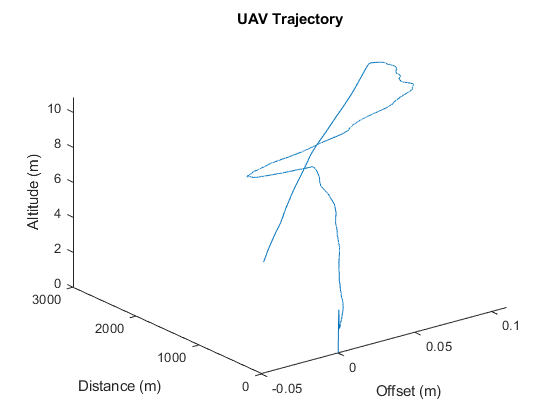

f5 = figure(5); clf;
plot3(pos(:,1), pos(:,2), pos(:,3));
%xlim([-1 1]);
xlabel("Offset (m)");
ylabel("Distance (m)");
zlabel("Altitude (m)");
title("UAV Trajectory");

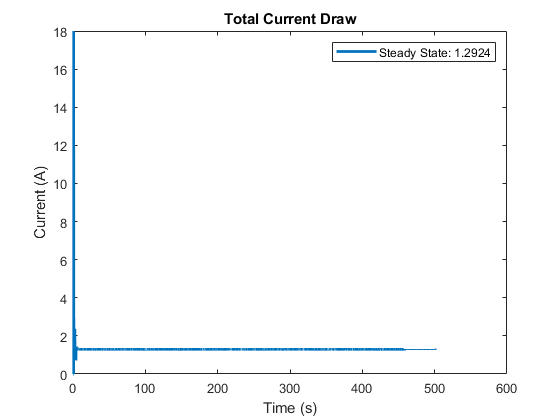

f6 = figure(6); clf;
plot(i_batt.Time, i_batt.Data, 'linewidth', 2);
title("Total Current Draw");
xlabel("Time (s)");
ylim([0 18]);
ylabel("Current (A)");
legend(["Steady State: " + num2str(i_batt.Data(1000))]);

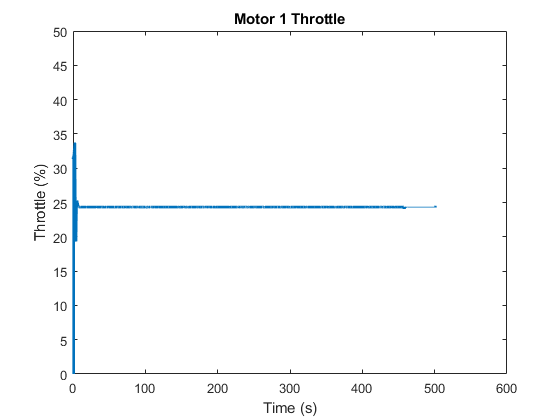

f7 = figure(7); clf;
plot(m1_throttle.Time, m1_throttle.Data, 'linewidth', 2);
title("Motor 1 Throttle");
xlabel("Time (s)");
ylabel("Throttle (%)");
ylim([0 50]);

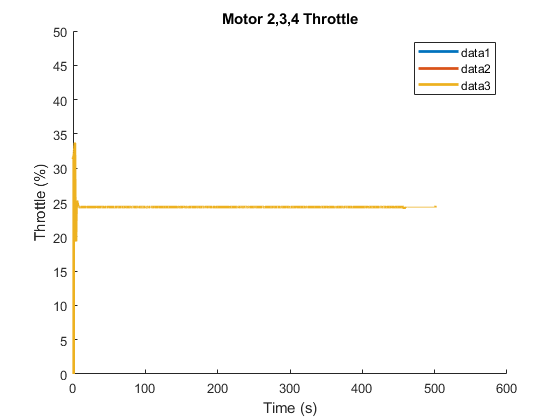

f8 = figure(8); clf;
hold on;
plot(m2_throttle.Time, m2_throttle.Data, 'linewidth', 2);
plot(m3_throttle.Time, m3_throttle.Data, 'linewidth', 2);
plot(m4_throttle.Time, m4_throttle.Data, 'linewidth', 2);
hold off;
title("Motor 2,3,4 Throttle");
xlabel("Time (s)");
ylabel("Throttle (%)");
ylim([0 50]);
legend()

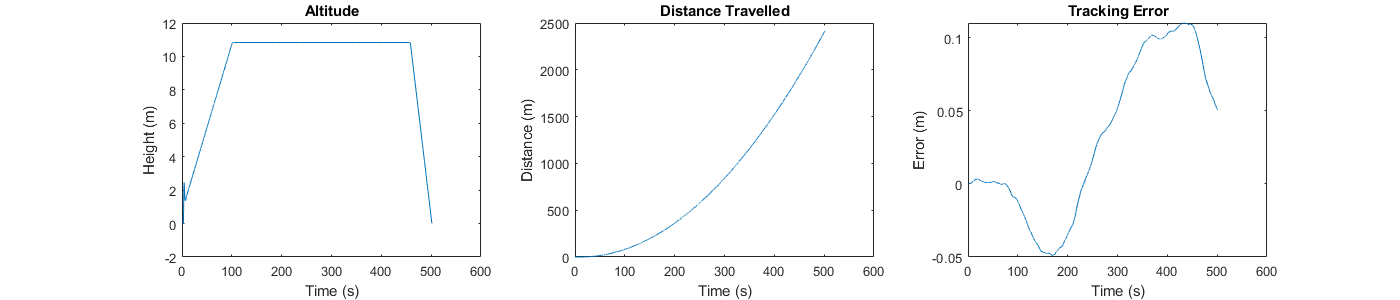

f9 = figure(9); clf;
f9.Position = [0 0 1400 300];
subplot(131);
plot(tout, pos(:,3));
title("Altitude");
xlabel("Time (s)");
ylabel("Height (m)");
subplot(132);
plot(tout, pos(:,2));
title("Distance Travelled");
xlabel("Time (s)");
ylabel("Distance (m)");
subplot(133);
plot(tout, pos(:,1));
title("Tracking Error");
xlabel("Time (s)");
ylabel("Error (m)");

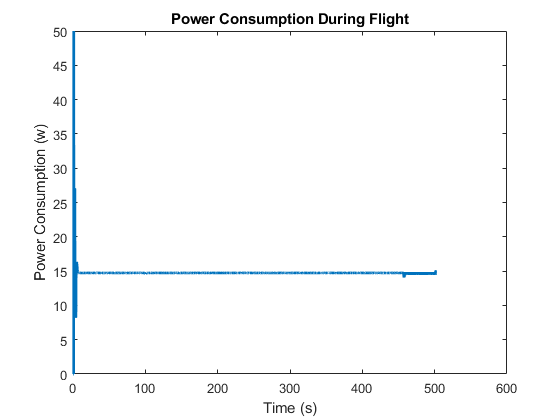

f10 = figure(10); clf;
plot(power.Time, power.Data, 'linew', 2);
title("Power Consumption During Flight");
xlabel("Time (s)");
ylabel("Power Consumption (w)");
ylim([0 50]);